[I, map] = imread('C:\dev\biomedeng\Associated Files\Chapter 13\double_chirp.tif')

I = 100×100 uint8 matrix
   255   255   255   255   253   251   247   241   231   217   198   175   147   116    83    52    24     6     0    10    37    80   133   186   231   254   247   209   147    78    21     0    24    89   172   237   253   209   122    36     0    38   133   225   253   193    83     6    24   129
   255   255   255   254   253   251   247   241   231   217   198   175   147   116    83    52    24     6     0    10    37    80   133   186   231   254   247   209   147    78    21     0    24    89   172   237   253   209   122    36     0    38   133   225   253   193    83     6    24   129
   255   255   255   254   253   251   247   240   231   217   198   175   147   116    83    52    24     6     0    10    37    80   133   186   231   254   247   209   147    78    22     0    24    89   172   237   253   209   122    37     0    38   133   225   253   193    83     6    24   129
   255   254   254   254   253   251   247   240   230   216   198   175


map =

     []




I = I(2:100, 2:100) %Remove the first point?

I = 99×99 uint8 matrix
   255   255   254   253   251   247   241   231   217   198   175   147   116    83    52    24     6     0    10    37    80   133   186   231   254   247   209   147    78    21     0    24    89   172   237   253   209   122    36     0    38   133   225   253   193    83     6    24   129   234
   255   255   254   253   251   247   240   231   217   198   175   147   116    83    52    24     6     0    10    37    80   133   186   231   254   247   209   147    78    22     0    24    89   172   237   253   209   122    37     0    38   133   225   253   193    83     6    24   129   233
   254   254   254   253   251   247   240   230   216   198   175   147   116    84    52    25     6     1    11    38    80   132   186   230   253   247   209   147    78    22     1    25    89   171   236   253   209   123    37     0    39   132   225   253   193    84     6    25   129   233
   253   253   253   252   250   246   239   229   216   197   175   147  


F = fft2(I, 128, 128)%take the Fourier transform

F = 1.0e+06 *

   1.2541 + 0.0000i  -0.2442 - 0.2254i  -0.0196 - 0.2533i   0.0928 - 0.1176i   0.0437 - 0.0104i  -0.0296 - 0.0274i  -0.0195 - 0.0829i   0.0287 - 0.0729i   0.0274 - 0.0182i  -0.0118 - 0.0001i  -0.0169 - 0.0287i   0.0185 - 0.0461i   0.0310 - 0.0263i   0.0013 - 0.0031i  -0.0149 - 0.0097i   0.0084 - 0.0324i   0.0220 - 0.0294i   0.0083 + 0.0012i   0.0002 - 0.0011i  -0.0033 - 0.0303i   0.0104 - 0.0183i   0.0245 - 0.0057i  -0.0047 - 0.0027i  -0.0004 - 0.0090i   0.0062 - 0.0278i   0.0194 - 0.0022i   0.0064 - 0.0048i  -0.0024 + 0.0000i   0.0009 - 0.0243i   0.0203 - 0.0069i   0.0059 - 0.0019i   0.0059 - 0.0015i  -0.0052 - 0.0085i   0.0121 - 0.0209i   0.0205 + 0.0025i  -0.0028 + 0.0058i  -0.0026 - 0.0142i   0.0137 - 0.0128i   0.0134 + 0.0000i   0.0035 + 0.0015i   0.0008 - 0.0060i   0.0067 - 0.0099i   0.0121 - 0.0051i   0.0088 + 0.0013i   0.0020 - 0.0005i   0.0030 - 0.0076i   0.0104 - 0.0075i   0.0115 + 0.0001i   0.0043 + 0.0024i   0.0012 - 0.0043i
  -0.2442 - 0.2254i   0.0137 + 0.0


F = abs(fftshift(F))%shift

F = 1.0e+06 *

    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0002    0.0002    0.0002    0.0001    0.0002    0.0003    0.0002    0.0002    0.0003    0.0004    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0004    0.0005    0.0004    0.0003    0.0005    0.0004    0.0004    0.0003    0.0006    0.0004    0.0003    0.0007    0.0003    0.0005    0.0005    0.0003    0.0006
    0.0001    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0002    0.0002    0.0001    0.0001    0.0002    0.0002    0.0002    0.0001    0.0002    0.0003    0.0002    0.0002    0.0002    0.0004    0.0004    0.0003    0.0004    0.0006    0.0006    0.0006    0.0009    0.0011    0.0010    0.0012    0.0013    0.0011    0.0010    0.0010    0.0009    0.0012    0.0011    0.0011    0.0009    0.0013    0.0010    0.0011    0.0012    0.0010    0.0011    0.0011    0.0010    

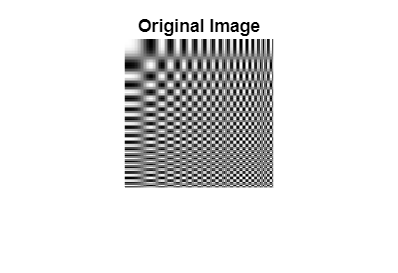


imshow(I)
title('Original Image')

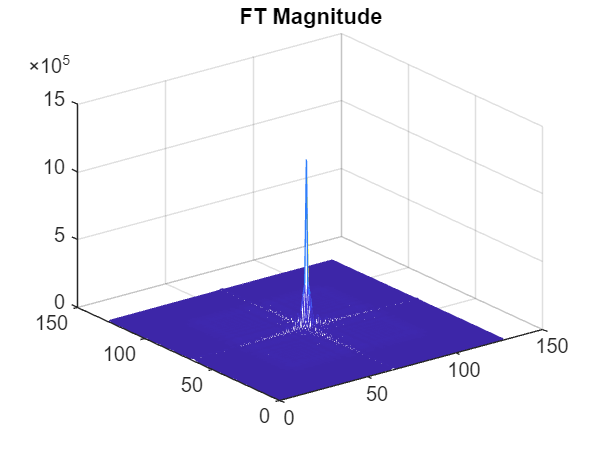

figure

mesh(F)
title('FT Magnitude')

figure
